Part A: Script to plot the interpolating polynomial using n = 40 adapted Chebyshev nodes for interval [−5, 5]

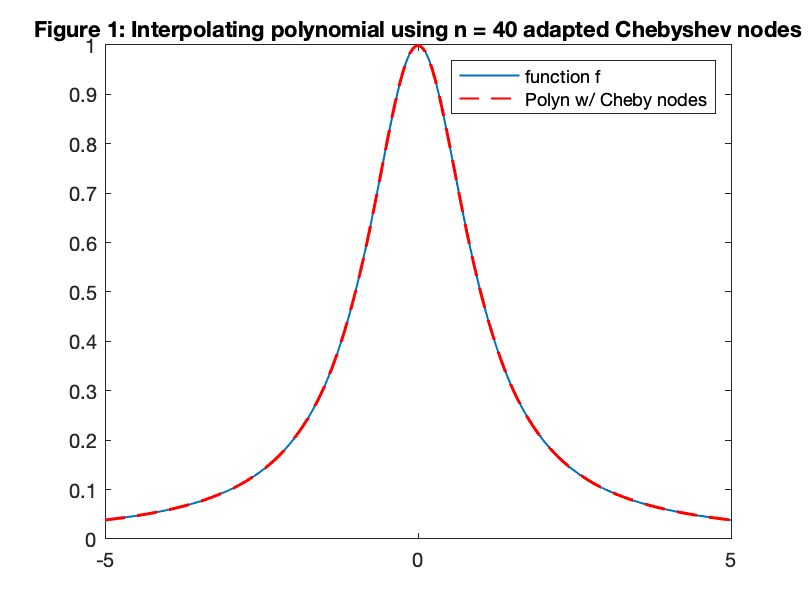

a = -5; b = 5; n = 40;
f = @(x) 1./(1+x.^2);

x_eval = linspace(a,b,200);
y_eval = f(x_eval);

xch = zeros(n,1);
for i = 1:n
    xch(i,1) = 5*cos(pi*((2*i)-1)/(2*n));
end
ych = f(xch);
y_evalch = evaluate_Newton(xch,ych,x_eval);

figure(1);
plot(x_eval,y_eval,'LineWidth',1)
hold on
plot(x_eval,y_evalch,'r--','LineWidth',1)
title('Figure 1: Interpolating polynomial using n = 40 adapted Chebyshev nodes')
legend('function f','Polyn w/ Cheby nodes')

Part B: Script to plot the interpolating polynomial polynomial using n = 40 equally space nodes on [−5, 5].

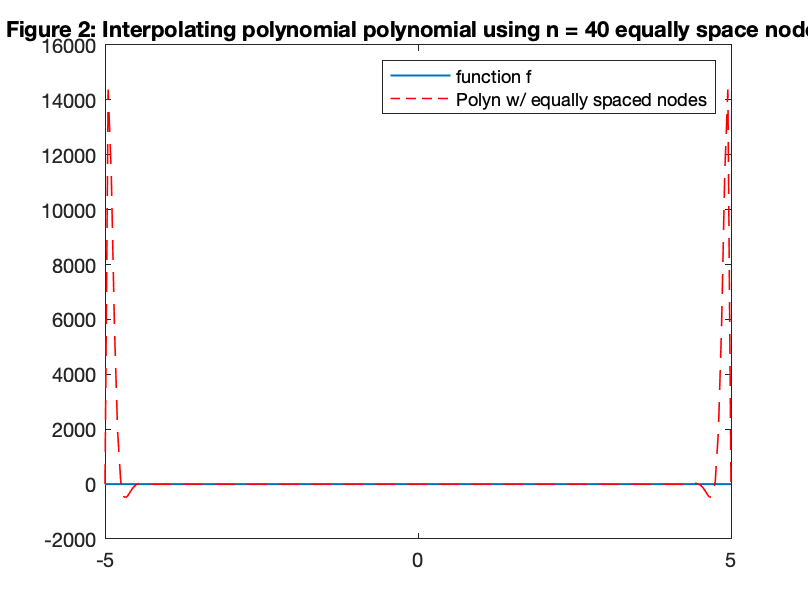

xeq = linspace(a,b,40);
yeq = f(xeq);
y_evaleq = evaluate_Newton(xeq,yeq,x_eval);

figure(2);
plot(x_eval,y_eval,'LineWidth',1)
hold on
plot(x_eval,y_evaleq,'r--','LineWidth',0.8)
title('Figure 2: Interpolating polynomial polynomial using n = 40 equally space nodes')
legend('function f','Polyn w/ equally spaced nodes')